### `Codes for ASK and FSK modulation and demodulation`: –

### `ASK Modulation and Demodulation -`

fs = 1e6; 
bit_rate = 1e3; 
fc = 100e3; 
Tb = 1 / bit_rate; 
N = 10; 
t = 0:1/fs:N*Tb - 1/fs; 
data = randi([0 1], 1, N);
data_stream = repelem(data, fs * Tb);
carrier = sin(2 * pi * fc * t);
ask_signal = data_stream .* carrier;
rectified = abs(ask_signal);

[b, a] = butter(5, (bit_rate * 2) / fs); 
filtered = filtfilt(b, a, rectified); % Zero-phase

threshold = 0.5 * (max(filtered) + min(filtered)); % Adaptive threshold
samples_per_bit = fs * Tb;

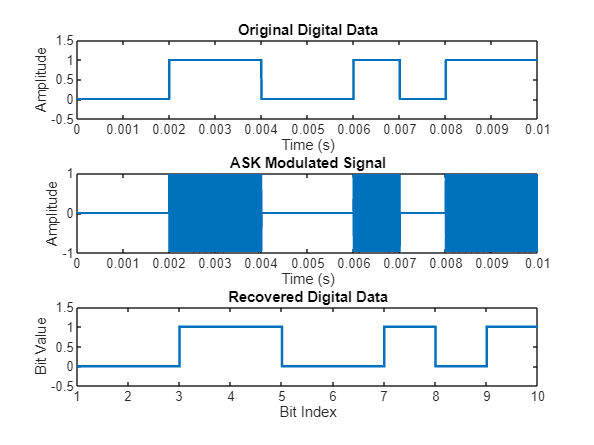


recovered_bits = zeros(1, N);
for i = 1:N
    center = round((i-1)*samples_per_bit + samples_per_bit/2);
    if center > length(filtered)
        center = length(filtered);
    end
    recovered_bits(i) = filtered(center) > threshold;
end

figure;
subplot(3,1,1);
plot(t, data_stream, 'LineWidth', 1.5);
title('Original Digital Data');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-0.5 1.5]);

subplot(3,1,2);
plot(t, ask_signal, 'LineWidth', 1.5);
title('ASK Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
stairs(recovered_bits, 'LineWidth', 1.5);
title('Recovered Digital Data');
xlabel('Bit Index');
ylabel('Bit Value');
ylim([-0.5 1.5]);

`In Amplitude Shift Keying (ASK), a digital signal is transmitted by controlling whether a carrier wave is present or absent. When the bit is 1, the carrier is sent at full amplitude; when the bit is 0, the carrier is turned off (or suppressed).`

`In MATLAB, this can be implemented by multiplying the binary data stream with a sinusoidal carrier. This produces an ASK waveform where the amplitude directly mirrors the data pattern.`

`For demodulation, the process usually involves:`

- `Rectifying the signal to extract its envelope.`

- `Passing it through a low-pass filter to remove high-frequency ripples.`

- `Using a comparator with a threshold to decide whether each bit is a 1 or 0, thereby reconstructing the original data.`

### `FSK Modulation and Demodulation` -

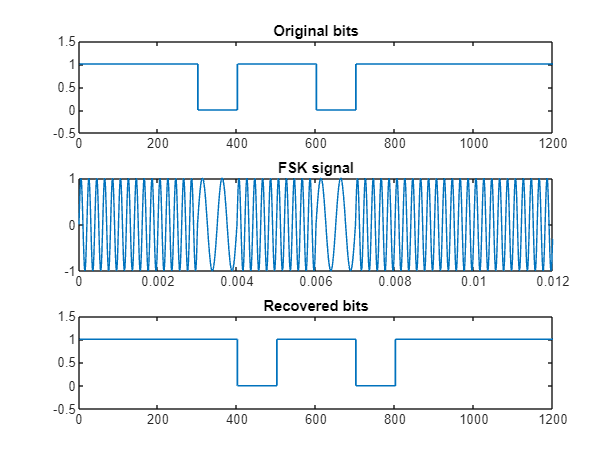

fs       = 100e3;        % sample rate
Rb       = 1e3;          % bit rate
Tb       = 1/Rb;         % bit time
Nb       = 12;           % number of bits
Npb      = round(fs*Tb); % samples per bit (100)
t_bit    = (0:Npb-1)/fs;
f0 = 2e3;  % bit-0 -> 2 cycles per bit
f1 = 5e3;  % bit-1 -> 5 cycles per bit
data = randi([0 1],1,Nb);
fsk = zeros(1,Npb*Nb);
w0  = sin(2*pi*f0*t_bit);
w1  = sin(2*pi*f1*t_bit);
for k = 1:Nb
    idx = (k-1)*Npb + (1:Npb);
    if data(k)==0
        fsk(idx) = w0;
    else
        fsk(idx) = w1;
    end
end
BW  = 800; % passband width
bp0 = designfilt('bandpassiir','FilterOrder',6, ...
      'HalfPowerFrequency1',f0-BW/2,'HalfPowerFrequency2',f0+BW/2, ...
      'SampleRate',fs);
bp1 = designfilt('bandpassiir','FilterOrder',6, ...
      'HalfPowerFrequency1',f1-BW/2,'HalfPowerFrequency2',f1+BW/2, ...
      'SampleRate',fs);
y0  = filter(bp0,fsk);
y1  = filter(bp1,fsk);
e0  = abs(hilbert(y0));
e1  = abs(hilbert(y1));
diff_env   = e1 - e0;
diff_mat   = reshape(diff_env, Npb, Nb);       % columns = bits
metric     = mean(diff_mat,1);                 % energy per bit
rx_bits    = metric > 0;
t = (0:numel(fsk)-1)/fs;
figure;
subplot(3,1,1);
stairs(repelem(data,Npb),'LineWidth',1); ylim([-0.5 1.5]);
title('Original bits');
subplot(3,1,2);
plot(t,fsk); xlim([0, Nb*Tb]); title('FSK signal');
subplot(3,1,3);
stairs(repelem(rx_bits,Npb),'LineWidth',1); ylim([-0.5 1.5]);
title('Recovered bits');

num_err = sum(rx_bits ~= data);
disp(['Bit errors: ' num2str(num_err) ' of ' num2str(Nb)]);

Bit errors: 4 of 12


`In Frequency Shift Keying (FSK), digital data is transmitted by switching the carrier wave between two distinct frequencies—one assigned to logic 0 and the other to logic 1.`

`In MATLAB, this can be implemented by:`

- `Generating a sine wave at frequency f₁ whenever the bit is 0`

- `Generating a sine wave at frequency f₂ whenever the bit is 1`

- `Concatenating these segments to form the complete FSK signal`

`For demodulation, the received signal is processed through two bandpass filters, one tuned to f₁ and the other to f₂, to isolate the respective frequency components. Envelope detection is then applied to each output, and during each bit period, the filter output with the stronger envelope indicates the transmitted bit.`

### `Report Questions: –`

## `1) FM vs. FSK Modulation`

- `FM (Frequency Modulation)`` changes the carrier’s frequency ``continuously`` in response to an ``analog signal`` such as voice or music.`

- `FSK (Frequency Shift Keying)`` changes (or “shifts”) the carrier between ``two fixed frequencies`` to represent binary ``0`` and ``1``.`

- `FM is an ``analog`` modulation method; FSK is a ``digital`` one.`

- `FM uses a ``wide range`` of frequencies, while FSK only switches between ``two specific tones``.`

## `2) AM vs. ASK Modulation`

- `AM (Amplitude Modulation)`` changes the carrier’s amplitude ``smoothly and continuously`` based on an ``analog input`` (like audio).`

- `ASK (Amplitude Shift Keying)`` switches the carrier’s amplitude between ``two levels`` (high/low or on/off) to represent digital ``0`` and ``1``.`

- `AM is ``analog`` and is widely used for broadcasting voice/music, while ASK is a ``digital modulation`` technique used for binary data transmission.`

## `3) Why FSK is often better than ASK`

- `Noise Immunity:`` FSK is more resistant to ``amplitude noise``, since it encodes data in frequency changes, while ASK is highly vulnerable to interference that alters amplitude.`

- `Bandwidth:`` ASK typically uses less bandwidth than FSK, but this comes ``at the cost of reliability``.`

- `Applications:`` FSK is a popular choice for ``modems, RFID systems, and low-power wireless devices`` due to its robustness. ASK is simpler and cheaper to implement but is less dependable in noisy environments.`

## `4) Similarities between ASK and FSK Demodulators`

- `Both use ``envelope detection``, which involves ``rectifying`` the signal and then using a ``low-pass filter`` to smooth it.`

- `Both require a ``comparator circuit`` to convert the smoothed analog envelope into clean digital “0” and “1” outputs.`

- `In both methods, demodulation works by ``isolating the relevant signal feature`` (amplitude for ASK, frequency for FSK) and then converting it back into binary data.`

### `Conclusion:`

`This lab provided valuable hands-on experience with two key digital modulation techniques — ``Amplitude Shift Keying (ASK)`` and ``Frequency Shift Keying (FSK)``. We observed how ``ASK`` transmits binary data by turning a carrier signal on or off, while ``FSK`` encodes data by switching between two different frequencies.`

`Through experimentation, we saw that ``ASK`` is simpler but more prone to errors in the presence of noise, as amplitude disturbances can easily corrupt the signal. ``FSK``, in contrast, showed better performance in noisy conditions due to its frequency-based encoding method, making it more reliable.`

`Beyond just reinforcing theoretical knowledge, this experiment deepened our understanding of the practical trade-offs between ``simplicity, bandwidth usage, and noise immunity``. These insights are essential as we progress toward designing and analyzing more advanced communication systems.`